% file = '/home/marcus/rockettrackingplatform/GazeboExport/data1';
file = 'C:\Users\unknown\UTS\UTS Rocketry Team - General\Individual Rockets\1) LPR\Marcus Hickel - Example - LPR\GazeboExport\data1';
bag = ros2bagreader(file);

msgs = readMessages(bag);

lgth = length(msgs)

lgth = 51872


for i = 1:lgth

    if msgs{i,1}.name(1) == "azimuth_joint"
        table.azimuth.position(1,i) = msgs{i,1}.position(1);
        table.azimuth.velocity(1,i) = msgs{i,1}.velocity(1);

        table.altitude.position(1,i) = msgs{i,1}.position(2);
        table.altitude.velocity(1,i) = msgs{i,1}.velocity(2);
    else
        table.altitude.position(1,i) = msgs{i,1}.position(1);
        table.altitude.velocity(1,i) = msgs{i,1}.velocity(1);

        table.azimuth.position(1,i) = msgs{i,1}.position(2);
        table.azimuth.velocity(1,i) = msgs{i,1}.velocity(2);
    end

end



% 
% adj = (table.azimuth.position(1)/(2*pi))-(floor(table.azimuth.position(1)/(2*pi)))*2*pi
% 
 for i = 1:lgth
     RadMult = table.azimuth.position(i)/(2*pi);
     RadNext = floor(table.azimuth.position(i)/(2*pi));

     rads = (RadMult - RadNext)*2*pi;

     table.azimuth.position(i) = rads;
 end

tablename = table.azimuth.position

tablename =     4.9423    4.9523    4.9623    4.9723    4.9823    4.9923    5.0023    5.0123    4.8613    4.8783    4.8953    4.9123    4.9293    4.9463    4.9633    4.9803    4.9973    5.0143    5.0223    5.0313    5.0323    5.0423    5.0483    5.0523    5.0623    5.0653    5.0723    5.0823    5.0823    5.0923    5.0993    5.1023    5.1123    5.1163    5.1223    5.1323    5.1333    5.1423    5.1503    5.1523    5.1623    5.1673    5.1723    5.1823    5.1843    5.1923    5.2013    5.2023    5.2123    5.2183



 [i, j, k] = find(table.azimuth.position>6.27); %Specificly Azimuth becuase it has the rotation peaks

 count = 0

count = 0

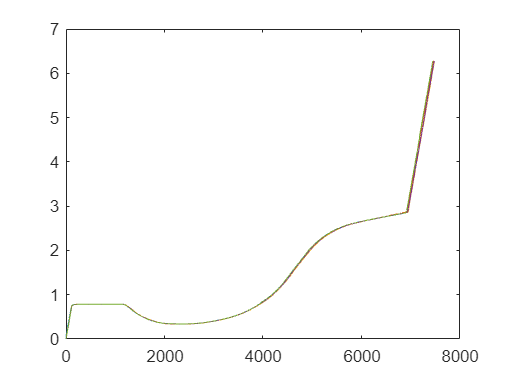


 for i = 1:length(j)
     index = i;
     if index == 18 
         index = 17;
     end
     if j(index)+1000 < j(index+1)
         count = count + 1;
         l(count) = j(index) ;
     
     end
 end

name = ["a", "b", "c", "d", "e", "f", "g"];

 for i = 1:length(l)
     try
     y.(name(i)) = tablename(l(i)+1:l(i+1)-1);
     catch
     y.(name(i)) = tablename(l(i)+1:l(end)-1);    
     end

 end
 
plot(y.a)
hold on
plot(y.b)
plot(y.c)
plot(y.d)
plot(y.e)
hold off


minlength = min([length(y.a),length(y.b),length(y.c),length(y.d),length(y.e)])

minlength = 7448


fn = fieldnames(y);
for i=1:numel(fn)  
    try
    New(:,i) = y.(fn{i})(1:minlength);
    catch
    end
end

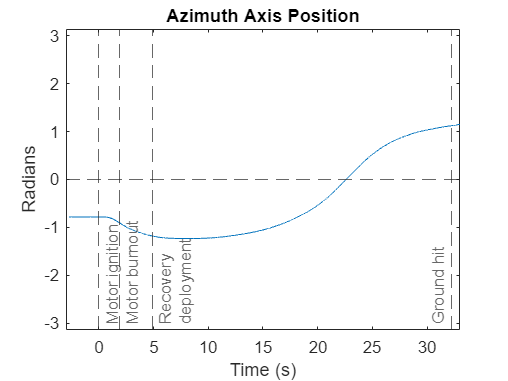


New(:,6) = mean(New,2);
start = 600;
finish = 6299;
timevar = linspace(-2.72, 33, finish-start+1);

plot(timevar, New(start:finish,6)-pi/2)
hold on
title('Azimuth Axis Position')
xlabel("Time (s)")
ylabel("Radians")
axis([-3, 33 -3.14, 3.14,])
yline(0,'--') 
%yline(max(abs(New(start:finish,6))),'-r',sprintf('Max %.2f Rad/s',max(abs(New(start:finish,6)))),'LabelHorizontalAlignment','center')
xline(0,'--','Motor ignition','LabelVerticalAlignment','bottom')
xline(1.86,'--','Motor burnout','LabelVerticalAlignment','bottom')
xline(4.861,'--',{'Recovery', 'deployment'},'LabelVerticalAlignment','bottom')
xline(32.2,'--','Ground hit','LabelVerticalAlignment','bottom','LabelHorizontalAlignment','left')

hold off

% count = floor(lgth/7463);
% hold on
% 
% for i = 1:count
%     xline(7463*i);
%     for j = 1:7463*i:lgth
%         table.azimuth.position(i) = table.azimuth.position(i)-2*pi*i;
%     end
% end
% 

% plot(table.azimuth.position)
% plot(table.azimuth.velocity)
% plot(table.altitude.position)
% plot(table.altitude.velocity)
% hold off